%% Text Size
set(0,'DefaultAxesFontsize',10);
set(0,'DefaultTextFontsize',10);
% set(0,'DefaultAxesFontWeight','bold');
% set(0,'DefaultTextFontWeight','bold');

%% Text Fonts
% set(0,'DefaultTextFontname','Arial')
% set(0,'DefaultAxesFontname','Arial')
set(0,'DefaultTextFontname','Times New Roman');
set(0,'DefaultAxesFontname','Times New Roman');

fig = figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',[5,5,18,7]);
set(gca,'Position', [0 0 1 1]);

h = subplot(1,2,1);
po = get(h, 'Position');
subplot('position', [po(1), po(2), po(3), po(4)]);
x = [1:0.25:3.5 5 1:0.25:3.5 5 ones(1,13) ones(1,13)*1.5 1:0.25:2.75 5];
y = [ones(1,12)*180 zeros(1,12) 0:15:180 0:15:180 ones(1,9)*90];
v = [1.05 1.1 1.2 1.14 1.08 1 0.95 0.96 0.97 0.98 0.99 1 ...
    -0.29 -0.21 0.25 0.65 0.7 0.65 0.7 0.75 0.78 0.81 0.84 1 ...
    -0.28 0.88 0.75 0.88 1.05 1.25 1.5 1.75 1.5 1.3 1.18 1.1 1.05 ...
    0.25 1.2 0.9 0.9 1 1.1 1.2 1.2 1.1 1 1.1 1.18 1.2 ...
    1.5 1.35 1.2 1.1 1.05 1.03 1.01 1.005 1];
[xq,yq] = meshgrid(1:.01:5, 0:1:180);
z4 = griddata(x,y,v,xq,yq,'cubic');

plot3(x,y,v,'.m')
hold on
mesh(xq,yq,z4)
title('Interacted Drag force')
leg = legend('Sample Points','Location','NorthWest')

leg =   Legend (Sample Points) - 属性:

         String: {'Sample Points'}
       Location: 'northwest'
    Orientation: 'vertical'
       FontSize: 8.5500
       Position: [0.1428 0.8199 0.1721 0.0679]
          Units: 'normalized'

  显示 所有属性


leg.ItemTokenSize = [10 10];
legend('boxoff');
clb = colorbar;
clb.Position(3) = 0.5 * clb.Position(3);
clb.Ticks = 0.5:0.25:1.5;
colormap jet
set(gca, 'CLim', [0.5 1.5]);
xlim([1 5]);
xticks(1:5);
ylim([0 180]);
yticks(0:45:180);
zticks(-0.5:0.5:2);
xlabel('R/D');
ylabel('\theta');
zlabel('C_{Interacted drag force}/C_D');

h = subplot(1,2,2);
po = get(h, 'Position');
subplot('position', [po(1), po(2), po(3), po(4)]);
x = [1:0.25:2.75 5 ones(1,13) ones(1,13)*1.5 ones(1,13)*5 1:0.25:5 1:0.25:5];
y = [ones(1,9)*90 0:15:180 0:15:180 0:15:180 zeros(1,17) ones(1,17)*180];
v = [0.5 0.25 0.15 0.12 0.095 0.085 0.07 0.06 0 ...
    0 -0.39 -0.24 -0.14 -0.2 0.05 0.5 0.56 0.5 0.3 0.1 0.15 0 ...
    0 -0.38 -0.38 -0.22 0.1 0.2 0.15 0.1 0 -0.12 -0.16 -0.17 0 ...
    zeros(1,13) zeros(1,17) zeros(1,17)];
[xq,yq] = meshgrid(1:.01:5, 0:1:180);
z4 = griddata(x,y,v,xq,yq,'cubic');

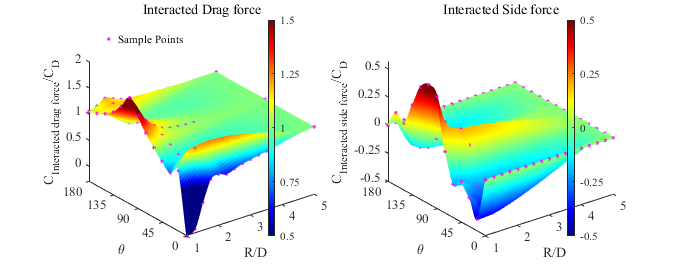

plot3(x,y,v,'m.')
hold on
mesh(xq,yq,z4)
title('Interacted Side force')
% legend('Sample Points','Location','NorthWest')
clb = colorbar;
clb.Position(3) = 0.5 * clb.Position(3);
clb.Ticks = -0.5:0.25:0.5;
colormap jet
set(gca, 'CLim', [-0.5 0.5]);
xlim([1 5]);
xticks(1:5);
ylim([0 180]);
yticks(0:45:180);
zticks(-0.5:0.25:0.5);
xlabel('R/D');
ylabel('\theta');
zlabel('C_{Interacted side force}/C_D');